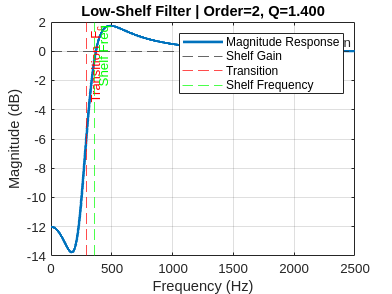

%% Interactive Shelving Filter Demo
% Move the sliders to see how the transition frequency and shelf frequency
% change in relation to each other.

%% Parameters (sliders in Live Editor)
fc = 290;       % Hz, transition (cutoff) frequency
gain_db =  -6;    % Gain in dB
orderN = 2;     % Filter order (higher = steeper)
Q = 1.4;      % Q-factor (1/sqrt(2) = Butterworth)
fs = 5000;      % Sampling frequency in Hz

%% Design low-shelf filter (RBJ Audio EQ Cookbook formula)
A = 10^(gain_db/40); 
w0 = 2*pi*fc/fs; 
alpha = sin(w0)/(2*Q) * sqrt( (A + 1/A)*(1/Q - 1) + 2 ); 

b0 =    A*((A+1) - (A-1)*cos(w0) + 2*sqrt(A)*alpha);
b1 =  2*A*((A-1) - (A+1)*cos(w0));
b2 =    A*((A+1) - (A-1)*cos(w0) - 2*sqrt(A)*alpha);
a0 =        (A+1) + (A-1)*cos(w0) + 2*sqrt(A)*alpha;
a1 =   -2*((A-1) + (A+1)*cos(w0));
a2 =        (A+1) + (A-1)*cos(w0) - 2*sqrt(A)*alpha;

b = [b0 b1 b2] / a0;
a = [1  a1/a0  a2/a0];

%% Cascade filter for higher order slopes
b_casc = b;
a_casc = a;
for k = 2:orderN
    b_casc = conv(b_casc, b);  % Cascade numerator
    a_casc = conv(a_casc, a);  % Cascade denominator
end

%% Frequency response
[H,f] = freqz(b_casc,a_casc,4096,fs);
mag = abs(H);

%% Find shelf frequency (95% of final gain)
final_gain = mag(end);
target_gain = 0.95 * final_gain;
idx_shelf = find(mag >= target_gain,1,'first');
shelf_freq = f(idx_shelf);

%% Plot
clf;
plot(f, 20*log10(mag),'LineWidth',2); hold on;
yline(20*log10(final_gain),'--','Shelf Gain');
xline(fc,'r--','Transition F_c');
xline(shelf_freq,'g--','Shelf Freq');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title(sprintf('Low-Shelf Filter | Order=%d, Q=%.3f',orderN,Q));
legend('Magnitude Response','Shelf Gain','Transition','Shelf Frequency');
grid on;